clear
clearvars
syms theta_1 theta_2 theta_3 theta_4 P_x P_y P_z
assume(theta_1,'real')
assume(theta_2,'real')
assume(theta_3,'real')
assume(theta_4,'real')

L=[145 104 104 90]*10^-3

L =     0.1450    0.1040    0.1040    0.0900


DH=[0, L(1), 0, (pi/2), 0, 0;
       0, 0, (L(2)), 0, 0, 0;
       0, 0, (L(3)),0, 0, 0;
       0, 0, L(4), pi/2 , 0, 0]

DH =          0    0.1450         0    1.5708         0         0
         0         0    0.1040         0         0         0
         0         0    0.1040         0         0         0
         0         0    0.0900    1.5708         0         0



Li(1)=Link(DH(1,:));
Li(2)=Link(DH(2,:));
Li(3)=Link(DH(3,:));
Li(4)=Link(DH(4,:));

Robot_1=SerialLink(Li,'name','Robot')

 
Robot_1 = 
 
Robot (4 axis, RRRR, stdDH, fastRNE)                             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.145|          0|      1.571|          0|
|  2|         q2|          0|      0.104|          0|          0|
|  3|         q3|          0|      0.104|          0|          0|
|  4|         q4|          0|       0.09|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1          

%Robot_q_1.tool = [1 0 0 L(4); 0 0 -1 0; 0 1 0 0; 0 0 0 1];
%A=simplify(Robot_q_1.A([1 2 3 4],[theta_1 theta_2 theta_3 theta_4]),"Steps",200)





q_1=[0.7853981633974483;
0.6530481254872835;
-1.7459907305629048;
1.6165413806739202]'

q_1 =     0.7854    0.6530   -1.7460    1.6165


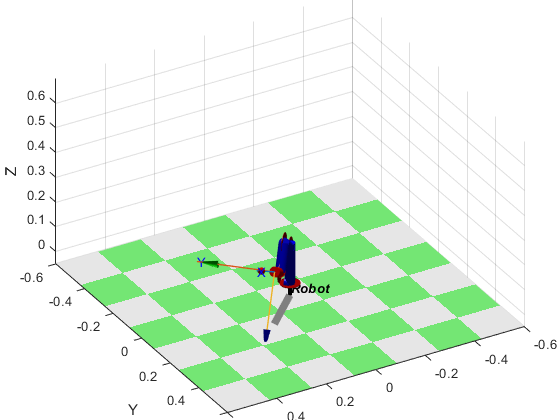

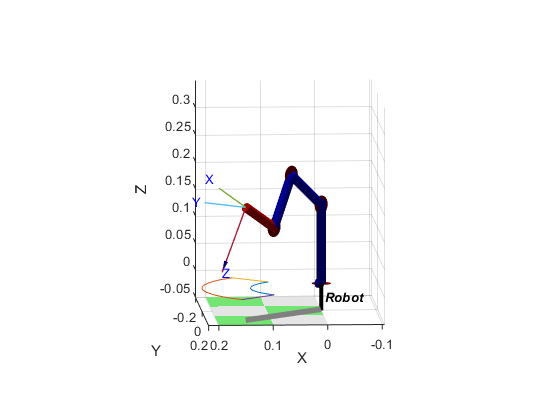



Robot_1.plot(q_1,'view',[150 30],'workspace',[-0.5 0.5 -0.5 0.5 -0.05 0.4],'joints','jointdiam',0.1);

Robot_1.fkine(q_1)

ans =     0.6124    0.7071    0.3536    0.1473
    0.6124   -0.7071    0.3536    0.1473
    0.5000    0.0000   -0.8660    0.1608
         0         0         0    1.0000


L_1=0.145

L_1 = 0.1450

L_2=0.105

L_2 = 0.1050

L_3=0.105

L_3 = 0.1050

L_4=0.095

L_4 = 0.0950

P_xmin=0.130

P_xmin = 0.1300

P_xmax=0.220

P_xmax = 0.2200

P_y=0

P_y = 0

P_z=0

P_z = 0

beta=0

beta = 0


Qmin=ikine4r(P_xmin,P_y,P_z,beta,L_1,L_2,L_3,L_4)

Qmin =          0   -0.5531   -1.5617    2.1148


Qmax=ikine4r(P_xmax,P_y,P_z,beta,L_1,L_2,L_3,L_4)

Qmax =          0   -0.4358   -0.8471    1.2829



N=200

N = 200

lim=45

lim = 45


tArr=linspace(0,5,N);
[s,sd,sdd] = lspb(-lim*pi/180, lim*pi/180, tArr);
sInt=int16(interp1([-150*pi/180 150*pi/180],[0 1023],s))

sInt = 200×1 int16 column vector
   358
   358
   358
   358
   358
   358
   359
   359
   359
   359


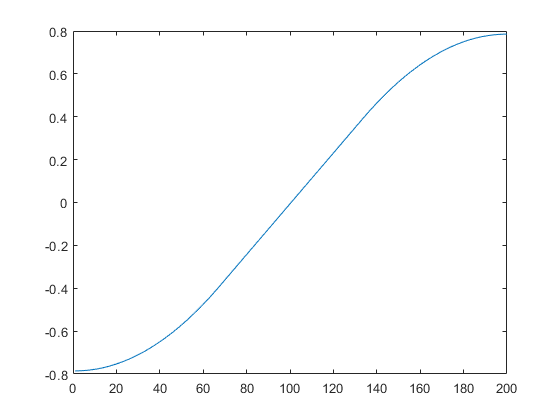


figure()
plot(s)


for i=1:200
    Pmin=Robot_1.fkine([[s(i) Qmin(2:4)]]);
    Pmax=Robot_1.fkine([[s(i) Qmax(2:4)]]);
    LimMin(i,:)=Pmin(1:3,4)';
    LimMax(i,:)=Pmax(1:3,4)';
end
clf

figure()

plot3(LimMin(:,1),LimMin(:,2),LimMin(:,3)-10)

hold on

plot3(LimMax(:,1),LimMax(:,2),LimMax(:,3)-10)

plot3([LimMax(1,1) LimMin(1,1)],[LimMax(1,2) LimMin(1,2)],[LimMax(1,3) LimMin(1,3)]-10)

plot3([LimMax(end,1) LimMin(end,1)],[LimMax(end,2) LimMin(end,2)],[LimMax(end,3) LimMin(end,3)]-10)

hold off

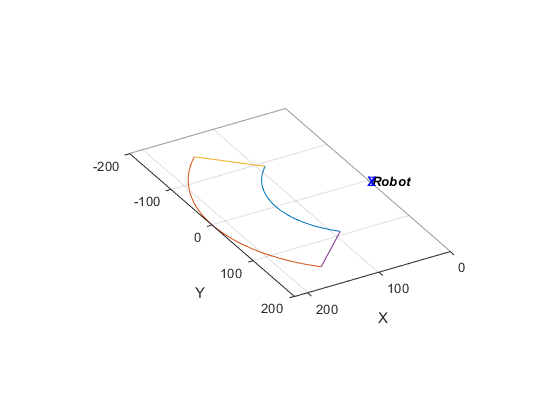

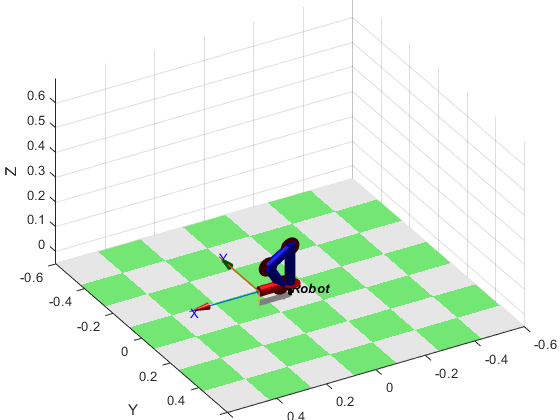

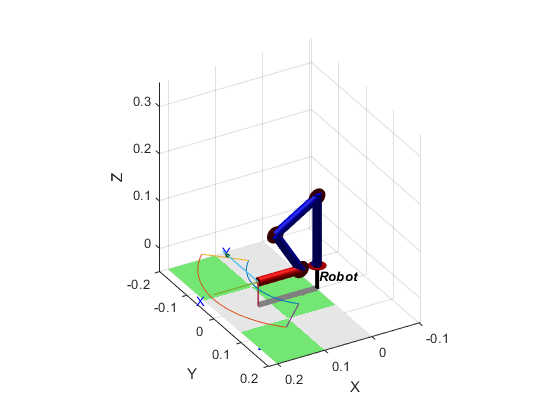

figure()
plot3(LimMin(:,1),LimMin(:,2),LimMin(:,3)-0.01)
hold on
plot3(LimMax(:,1),LimMax(:,2),LimMax(:,3)-0.01)
plot3([LimMax(1,1) LimMin(1,1)],[LimMax(1,2) LimMin(1,2)],[LimMax(1,3) LimMin(1,3)]-0.01)
plot3([LimMax(end,1) LimMin(end,1)],[LimMax(end,2) LimMin(end,2)],[LimMax(end,3) LimMin(end,3)]-0.01)
Robot_1.plot(Qmin,'view',[150 30],'workspace',[-0.05 0.3 -0.3 0.3 -0.05 0.4],'joints','jointdiam',0.1);

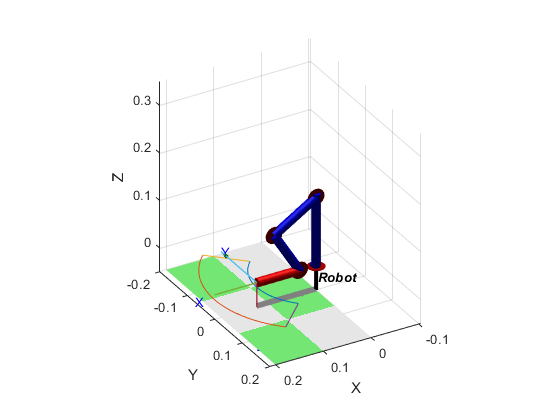

hold off
zlim([-0.05 0.35])

figure()
Robot_1.animate(Qmax)
Robot_1.fkine(Qmax)

ans =     1.0000    0.0000   -0.0000    0.2138
   -0.0000   -1.0000   -0.0000   -0.0000
   -0.0000    0.0000   -1.0000    0.0014
         0         0         0    1.0000


pause(1)
Robot_1.animate(Qmin)

Robot_1.fkine(Qmin)

ans =     1.0000   -0.0000    0.0000    0.1247
    0.0000   -1.0000   -0.0000   -0.0000
    0.0000    0.0000   -1.0000    0.0014
         0         0         0    1.0000



q2=interp1([1023 0],[-150*pi/180 150*pi/180],713)
q3=interp1([1023 0],[-240*pi/180 60*pi/180],962)
q4=interp1([1023 0],[-150*pi/180 150*pi/180],162)

q=[0 q2 q3 q4]
Robot_1.plot(q,'view',[150 30],'workspace',[-0.05 0.3 -0.3 0.3 -0.05 0.4],'joints','jointdiam',0.1);
Robot_1.fkine(q)

## Carga

qHome=[0 0 0 0]

qHome =      0     0     0     0


Robot_1.fkine(qHome)

ans =     1.0000         0         0    0.2980
         0   -1.0000   -0.0000         0
         0    0.0000   -1.0000    0.1450
         0         0         0    1.0000


Robot_1.animate(qHome)


Z_marcador=0

Z_marcador = 0

P_Harriba=[0.15 -0.15 Z_marcador+0.05 0]

P_Harriba =     0.1500   -0.1500    0.0500         0



qHarriba=ikine4r(P_Harriba(1),P_Harriba(2),P_Harriba(3),P_Harriba(4),L_1,L_2,L_3,L_4)

qHarriba =    -0.7854    0.0882   -1.5393    1.4511


Robot_1.fkine(qHarriba)

ans =     0.7071   -0.7071   -0.0000    0.1457
   -0.7071   -0.7071   -0.0000   -0.1457
    0.0000    0.0000   -1.0000    0.0509
         0         0         0    1.0000


Robot_1.animate(qHarriba)


P_Habajo=[0.15 -0.15 Z_marcador 0]

P_Habajo =     0.1500   -0.1500         0         0


qHabajo=ikine4r(P_Habajo(1),P_Habajo(2),P_Habajo(3),P_Habajo(4),L_1,L_2,L_3,L_4)

qHabajo =    -0.7854   -0.4127   -0.9573    1.3700


Robot_1.fkine(qHabajo)

ans =     0.7071   -0.7071   -0.0000    0.1457
   -0.7071   -0.7071   -0.0000   -0.1457
    0.0000    0.0000   -1.0000    0.0014
         0         0         0    1.0000


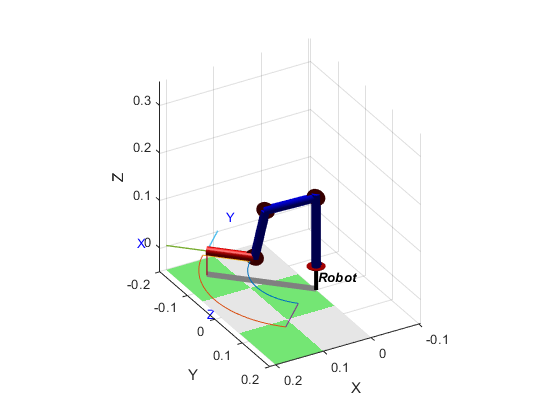

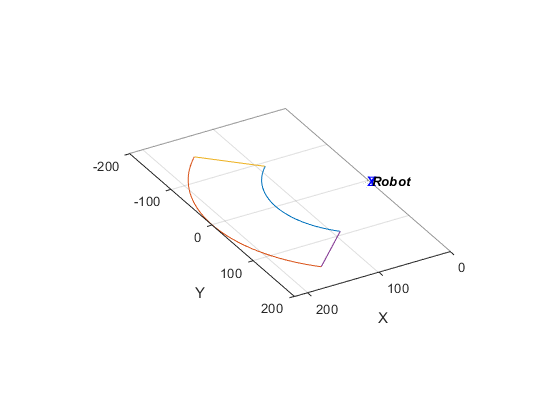

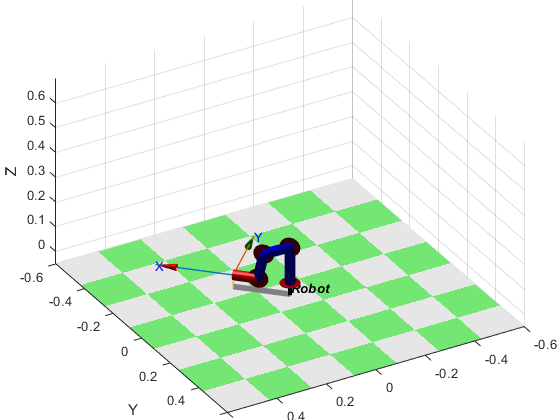

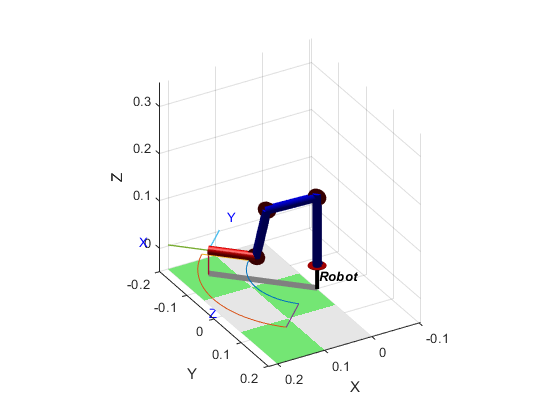

Robot_1.animate(qHabajo)

## Dibujos

PuntosA=[100 150;150 125;100 100;125 112.5;125 137.5]*0.001

PuntosA =     0.1000    0.1500
    0.1500    0.1250
    0.1000    0.1000
    0.1250    0.1125
    0.1250    0.1375


PuntosJ=[150 100;150 50;150 75;100 75;100 100]*0.001

PuntosJ =     0.1500    0.1000
    0.1500    0.0500
    0.1500    0.0750
    0.1000    0.0750
    0.1000    0.1000


PuntosTri=[100,0;100 50;143.3 25;100,0]*0.001

PuntosTri =     0.1000         0
    0.1000    0.0500
    0.1433    0.0250
    0.1000         0


Rads=linspace(0,2*pi,50);
PuntosCirc=[125+25*sin(Rads);-25+25*cos(Rads)]'*0.001

PuntosCirc =     0.1250         0
    0.1282   -0.0002
    0.1313   -0.0008
    0.1344   -0.0018
    0.1373   -0.0032
    0.1400   -0.0050
    0.1424   -0.0070
    0.1445   -0.0094
    0.1464   -0.0120
    0.1479   -0.0149


PuntosR1=[100 -50;100 -100]*0.001

PuntosR1 =     0.1000   -0.0500
    0.1000   -0.1000


PuntosR2=[125 -50;125 -100]*0.001

PuntosR2 =     0.1250   -0.0500
    0.1250   -0.1000


PuntosR3=[150 -50;150 -100]*0.001

PuntosR3 =     0.1500   -0.0500
    0.1500   -0.1000


PuntosEQ=[100 -125;110 -125;120 -125;130 -125;140 -125;150 -125]*0.001

PuntosEQ =     0.1000   -0.1250
    0.1100   -0.1250
    0.1200   -0.1250
    0.1300   -0.1250
    0.1400   -0.1250
    0.1500   -0.1250


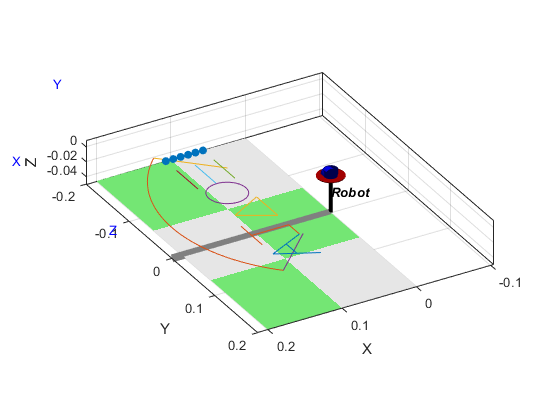

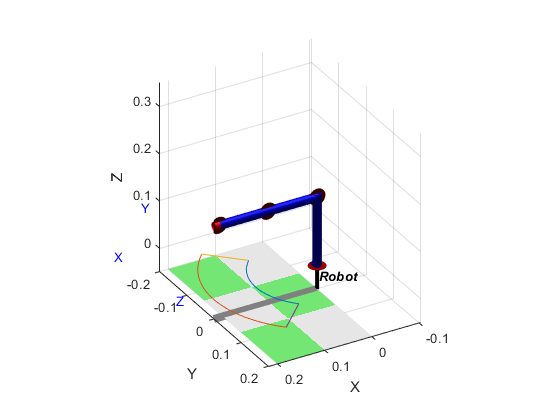

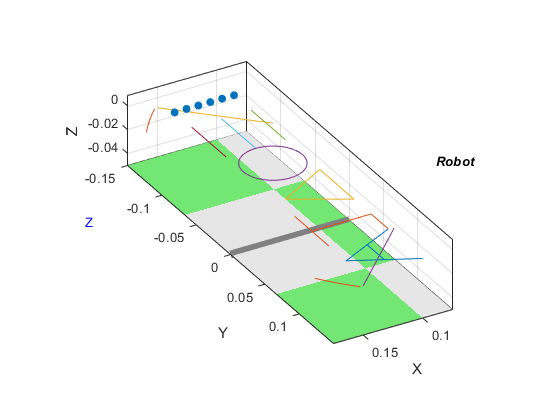

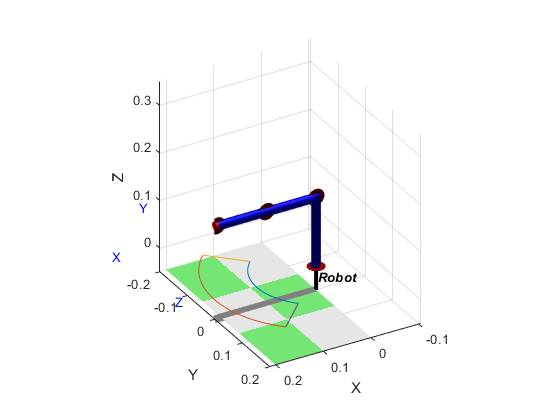

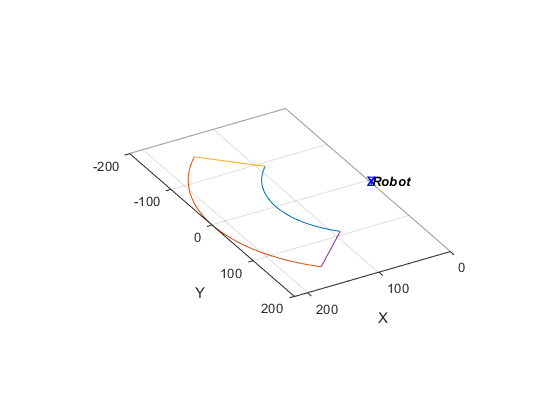

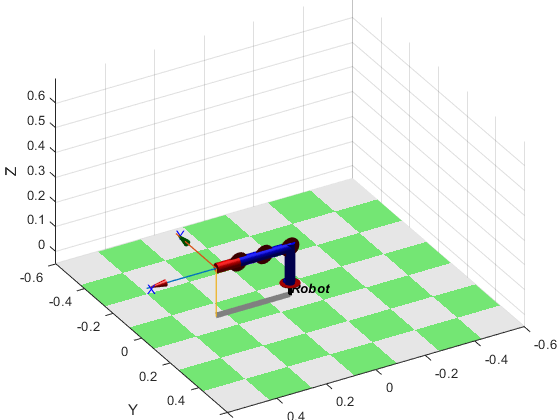

figure()
plot(PuntosA(:,1),PuntosA(:,2))
hold on
plot(PuntosJ(:,1),PuntosJ(:,2))
plot(PuntosTri(:,1),PuntosTri(:,2))
plot(PuntosCirc(:,1),PuntosCirc(:,2))
plot(PuntosR1(:,1),PuntosR1(:,2))
plot(PuntosR2(:,1),PuntosR2(:,2))
plot(PuntosR3(:,1),PuntosR3(:,2))
scatter(PuntosEQ(:,1),PuntosEQ(:,2),"filled")
plot3(LimMax(:,1),LimMax(:,2),LimMax(:,3)-0.01)
plot3([LimMax(1,1) LimMin(1,1)],[LimMax(1,2) LimMin(1,2)],[LimMax(1,3) LimMin(1,3)]-0.01)
plot3([LimMax(end,1) LimMin(end,1)],[LimMax(end,2) LimMin(end,2)],[LimMax(end,3) LimMin(end,3)]-0.01)
Robot_1.plot(Qmin,'view',[150 30],'workspace',[-0.05 0.3 -0.3 0.3 -0.05 0.4],'joints','jointdiam',0.1);
hold off
Robot_1.animate(qHome)

## Descargar la herramienta



qHarriba=ikine4r(0.100,0.150,0,0,L_1,L_2,L_3,L_4)

qHarriba =     0.9828   -0.3974   -1.2835    1.6809


Robot_1.fkine(qHarriba)

ans =     0.5547    0.8321    0.0000    0.0968
    0.8321   -0.5547   -0.0000    0.1452
    0.0000    0.0000   -1.0000    0.0014
         0         0         0    1.0000


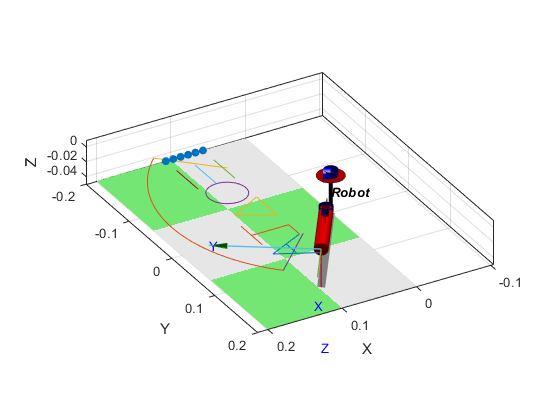

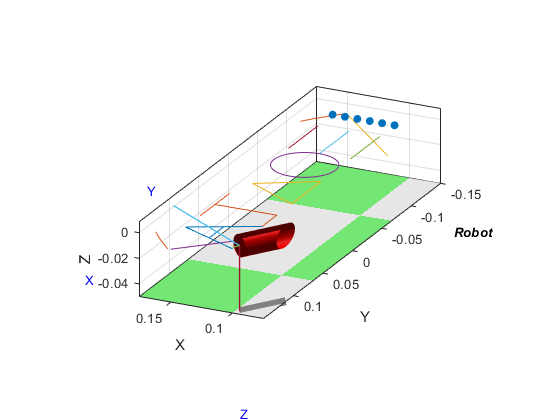

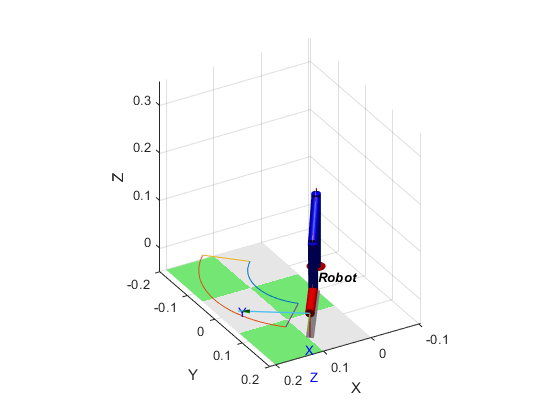

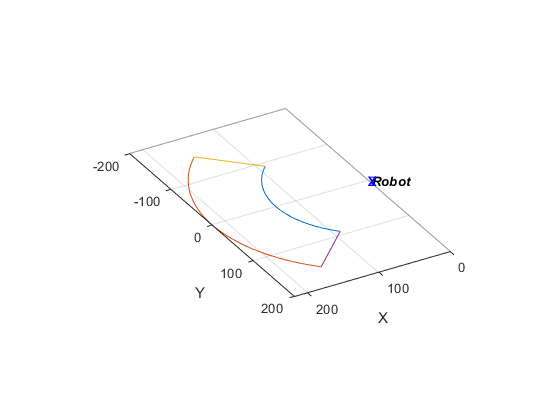

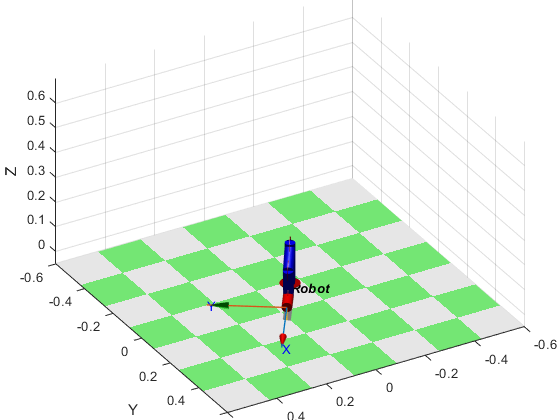

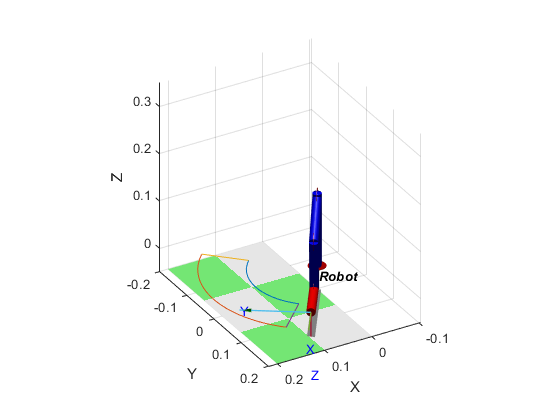

Robot_1.animate(qHarriba)

function T=Ftheta_1(P_x,P_y)
    T=atan2(P_y,P_x);
end

function T=Ftheta_2(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)
    R=sqrt(P_x^2+P_y^2);
    D_r=R-L_4*cos(beta);
    D_z=P_z-L_4*sin(beta)-L_1;
    T=2*atan((2*D_z*L_2 + sqrt(- D_r^4 - 2*D_r^2*D_z^2 + 2*D_r^2*L_2^2 + 2*D_r^2*L_3^2 - D_z^4 + 2*D_z^2*L_2^2 + 2*D_z^2*L_3^2 - L_2^4 + 2*L_2^2*L_3^2 - L_3^4))/(D_r^2 + 2*D_r*L_2 + D_z^2 + L_2^2 - L_3^2));
end

function T=Ftheta_3(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)
    R=sqrt(P_x^2+P_y^2);
    D_r=R-L_4*cos(beta);
    D_z=P_z-L_4*sin(beta)-L_1;
    T=-2*atan(sqrt((- D_r^2 - D_z^2 + L_2^2 + 2*L_2*L_3 + L_3^2)*(D_r^2 + D_z^2 - L_2^2 + 2*L_2*L_3 - L_3^2))/(D_r^2 + D_z^2 - L_2^2 + 2*L_2*L_3 - L_3^2));
end

function T=Ftheta_4(beta,theta_2,theta_3)
    T=beta-theta_2-theta_3;
end

function T=ikine4r(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)
    T1=Ftheta_1(P_x,P_y);
    T2=Ftheta_2(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4);
    T3=Ftheta_3(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4);
    T4=Ftheta_4(beta,T2,T3);
    T=[T1,T2,T3,T4];
end